# Chapter 5 - Frequency Response Anaysis 

## Section 1 : Plotting Bode Diagrams with Matlab

clear all
clc

## 5-1 Plot a body diagram of the transfer function

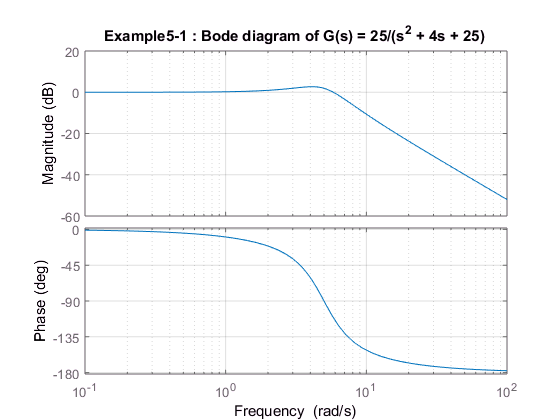

num1 = [25];
den1 = [1 4 25];

figure 
bode(num1, den1), grid
title('Example5-1 : Bode diagram of G(s) = 25/(s^2 + 4s + 25)')

## 5-2 Plot a Bode Diagram of the transfer function

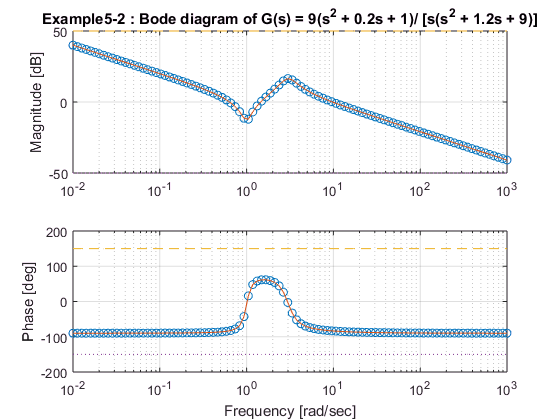

num2 = 9 * [1 0.2 1];
den2 = [1 1.2 9 0];

w = logspace(-2, 3, 100);  %100 equally spaced log points between 0.01 - 100 rad/sec
[mag, ph, w] = bode(num2, den2, w);
magdB = 20 * log10(mag);  %convert to db 

%Magnitude limits (create lines between +/-50 dB) 
    dBmax = 50 * ones(1, 100);
    dBmin = -50 * ones(1, 100);

%Phase limits (create lines between +/-150 deg)
pmax = 150 * ones(1, 100);
pmin = -150 * ones(1, 100);

figure 
subplot(211); semilogx(w, magdB, 'o', w, magdB, '-', w, dBmax, '--', w, dBmin, ':'),grid
ylabel('Magnitude [dB]')
title('Example5-2 : Bode diagram of G(s) = 9(s^2 + 0.2s + 1)/ [s(s^2 + 1.2s + 9)]')
subplot(212); semilogx(w, ph, 'o', w, ph, '-', w, pmax, '--', w, pmin, ':'),grid
xlabel('Frequency [rad/sec]')
ylabel('Phase [deg]')

## 5-3 Bode diagram of system defined in state space

Consider the system xd = Ax + Bu && y = Cx + Du

Use bode(A, B, C, D) to create a bode plot for each input 

Use bode(A, B, C, D, iu), where iu is the ith input of the system

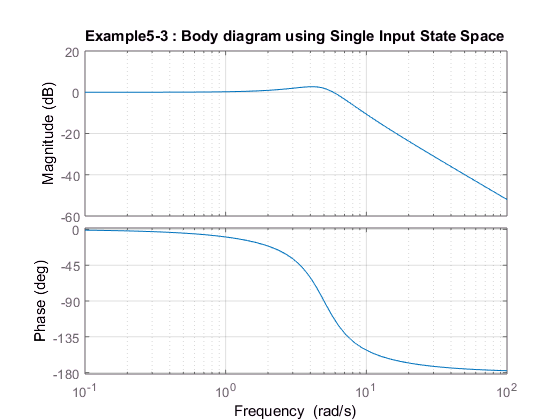


% Define system 
A = [0 1 ; -25 -4];
B = [0; 25];
C = [1 0];
D = 0;

figure
bode(A, B, C, D), grid
title('Example5-3 : Body diagram using Single Input State Space')

## 5-4 Obtain the sinusoidal transfer functions Y1/U1, Y2/U1, Y1/U2, Y2/U2

clear
clc

%define system 
A = [0 1; -25 -4];
B = [1 1; 0 1];
C = [1 0; 0 1];
D = 0;

%define transfer function: G(s) = C(sI - A)^-1*B + D
syms s y1 y2 u1 u2
Gs = C * inv(s*eye(2) - A) * B + D;
Gs = simplify(Gs);

>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>


 Transfer Function, G(s) = 


Transfer Function, G(s) is equal to: 

pretty(Gs)

/      s + 4           s + 5     \
|  -------------,  ------------- |
|   2               2            |
|  s  + 4 s + 25   s  + 4 s + 25 |
|                                |
|         25           s - 25    |
| - -------------, ------------- |
|    2              2            |
\   s  + 4 s + 25  s  + 4 s + 25 /




%Inputs 
U1 = [u1; 0];
U2 = [0; u2];

% Determine Y1/U1, Y2/U1 Transfer Functions, assuming U2 = 0
y1 = Gs*U1;

>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>


[ Assuming U2 = 0 ] 


 Assuming U2 = 0 

disp('Y1/U1 = '); pretty(y1(1)/U1(1))

Y1/U1 = 
    s + 4
-------------
 2
s  + 4 s + 25



disp('Y2/U1 = '); pretty(y1(2)/U1(1))

Y2/U1 = 
        25
- -------------
   2
  s  + 4 s + 25



% Determine Y1/U2, Y2/U2 Transfer Functions, assuming U1 = 0
y2 = Gs*U2;

>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>


[ Assuming U1 = 0 ] 


Assuming U1 = 0 

disp('Y1/U2 = '); pretty(y1(1)/U2(2))

Y1/U2 = 
    u1 (s + 4)
------------------
     2
u2 (s  + 4 s + 25)



disp('Y2/U2 = '); pretty(y1(2)/U2(2))

Y2/U2 = 
         25 u1
- ------------------
       2
  u2 (s  + 4 s + 25)



## 5-5 Plot bode plots for each tf in example 5-4

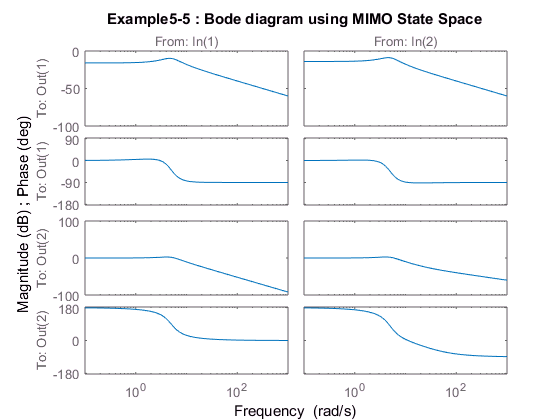

clear
clc

A = [0 1; -25 -4];
B = [1 1; 0 1];
C = [1 0 ;0 1];
D = [0 0; 0 0];

figure
bode(A, B, C, D), grid
title('Example5-5 : Bode diagram using MIMO State Space') 
grid

## 5-6 Closed Loop Bode plot for multiple values of K

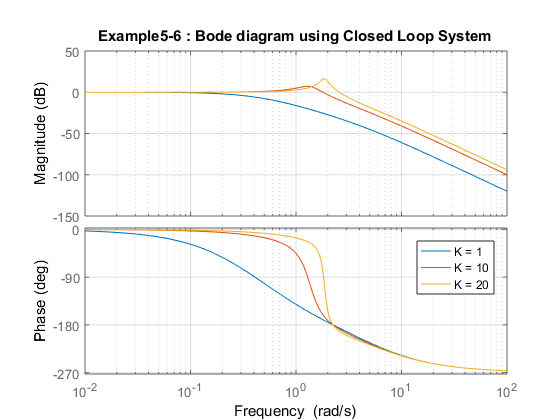

clear
clc

%define three gain values
K = [1; 10; 20];

for n = 1:3;
    %transfer function
    Gs = tf([K(n)], [1 6 5 0]);

    %Closed loop TF 
    G_CL = Gs/(1 + Gs);
    g_CL = simplify(G_CL);


    bode(g_CL), grid
    legend('K = 1', 'K = 10', 'K = 20')
    title('Example5-6 : Bode diagram using Closed Loop System')
    hold on
end